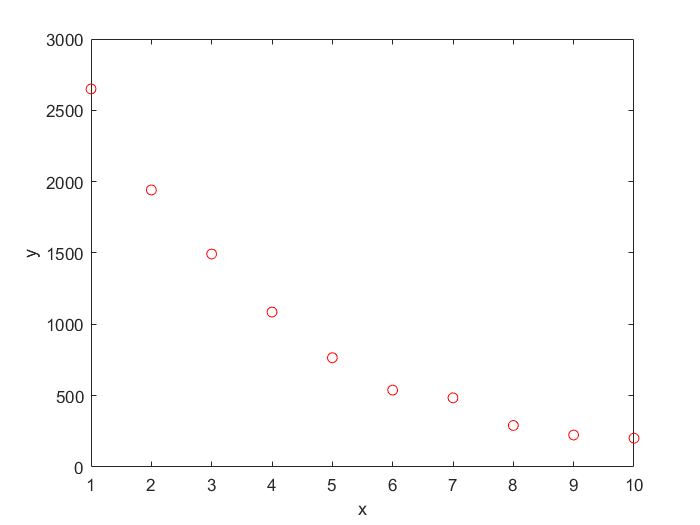

clear all
clc
x=1:10;
y=[2650,1942,1493,1086,766,539,485,291,224,202];
for i=1:10
    plot(x(i),y(i),'or');
    hold on
end
xlabel('x');
ylabel('y');

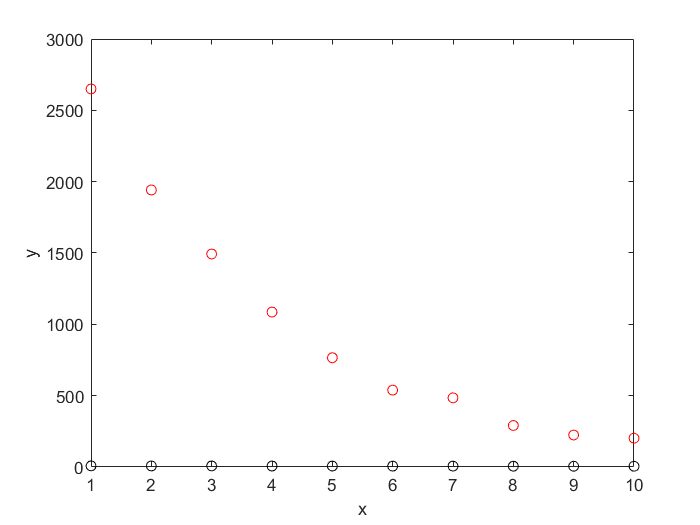

clear all
clc
x=1:10;
y=[2650,1942,1493,1086,766,539,485,291,224,202];
z=zeros(size(y));
N=length(y);
for i =1:N
    z(i)=log(y(i));
    plot(x(i),z(i),'ok');
end
xlabel('x');
ylabel('y');

clear all
clc
x=1:10;
y=[2650,1942,1493,1086,766,539,485,291,224,202];
z=zeros(size(y));
N=length(y);
for i =1:N
    z(i)=log(y(i));
end
[p,s]=polyfit(x,z,1)

p =    -0.2984    8.1671


s = 包含以下字段的 struct :
        R: [2×2 double]
       df: 8
    normr: 0.2316


%开始多元回归
clear all
clc
x1=[1.376,1.375,1.387,1.401,1.412,1.428,1.445,1.477];
x2=[0.450,0.175,0.485,0.5,0.535,0.545,0.55,0.575];
x3=[2.170,2.554,2.676,2.713,2.823,3.088,3.122,3.262];
x4=[5.19,1.161,0.5346,0.9589,2.0239,1.0499,1.1065,1.1387];
y=[5.19,5.3,5.6,5.82,6,6.06,6.45,6.95];
save data x1 x2 x3 x4 y%保存数据
load data %取出数据
y=[y'];
x=[ones(size(x1')),x1',x2',x3',x4'];
[b,bint,r,rint,stats]=regress(y,x)

b =   -18.5855
   18.2936
    0.3429
   -0.4811
   -0.0919


bint =   -31.9096   -5.2614
    5.7187   30.8684
   -0.7810    1.4669
   -2.0888    1.1267
   -0.2637    0.0798


r =    -0.0297
    0.0072
   -0.0175
   -0.0020
    0.1156
   -0.0826
    0.0163
   -0.0074


rint =    -0.0686    0.0092
   -0.0058    0.0202
   -0.3010    0.2659
   -0.3365    0.3325
   -0.0178    0.2491
   -0.2056    0.0405
   -0.3659    0.3985
   -0.1798    0.1651


stats =     0.9909   81.9158    0.0021    0.0073
